# LLENTAB - Prefabricated steel hall

% clc;clear all;clearvars;uqlab;close all; addpath 'Functions\'

## Vazník - Dolní pás

Section properties

section.h_w =  119.0   * 10^-3; % m
section.b   =  110.0   * 10^-3; % m
section.c   =   42.0   * 10^-3; % m
section.e_1 =   55.8   * 10^-3; % m
section.A_s = 1615.93  * 10^-6; % m^2
section.t   =    4.0   * 10^-3; % m
section.n_cross = 2           ; % ea
section.d_0 = 12.5 * 10^-3    ; % m
section.X = 1                 ;
section.A_net = section.A_s - section.t * (section.n_cross * section.d_0 * 2 / section.X);

% Material properties
section.f_u =   480.0  * 10^3 ; % kN/m
section.f_y =   420.0  * 10^3  ; % kN/m

% Internal forces - characteristic values
forces.G_s.N_k = 100.28 ; %kN
forces.G_p.N_k = 61.60 ; %kN
forces.Q.N_k = 140.47 ; %kN

## Posouzení dle eurokódu


$$E_d = \gamma_g \cdot G + \gamma_q \cdot Q \\
R_d = \min \left( \frac{A_s \cdot f_y}{\gamma_{M0}} ; \frac{A_{net}  \cdot f_u}{\gamma_{M2}} \right)$$


EN.gamma_q = 1.50 ;
EN.gamma_g = 1.35 ;
EN.gamma_M0 = 1.00 ;
EN.gamma_M2 = 1.25 ;
EN.E_d = (forces.G_s.N_k + forces.G_p.N_k) * EN.gamma_g + forces.Q.N_k * EN.gamma_q; % kN
EN.R_d_l = 0.9 * section.A_s * section.f_y / EN.gamma_M0;
EN.R_d_net = section.A_net * section.f_u / EN.gamma_M2;
EN.R_d = min(EN.R_d_net,EN.R_d_l);  % CHECK
EN.ration = EN.E_d / EN.R_d;
EN.A_s_en = EN.E_d / section.f_y * EN.gamma_M0; %m^2

## Probabilistic reliability analysis

% Probablistic models of variables
% Yeild strength

model.f_y.V_x = 5 / 100; % percent
model.f_y.ratio = 1.09 ;
model.f_y.Dist = 'Lognormal';
model.f_y.nominal = section.f_y;
model.f_y.variable = createUQVariable(model.f_y, 'fy');
InputOpts.Marginals(1) = model.f_y.variable;

% Geometry
model.a.V_x = 3 / 100; % percent
model.a.ratio = 1.00 ;
model.a.Dist = 'Gaussian';
model.a.nominal = section.A_net; % CHECK
model.a.variable = createUQVariable(model.a, 'A');
InputOpts.Marginals(2) = model.a.variable;

% Self weight load
model.G_s.V_x = 5 / 100 ;% percent
model.G_s.ratio = 1.00 ;
model.G_s.Dist = 'Gaussian';
model.G_s.nominal = forces.G_s.N_k;
model.G_s.variable = createUQVariable(model.G_s, 'G');
InputOpts.Marginals(3) = model.G_s.variable;

% Pernament load
model.G_p.V_x = 10 / 100 ;% percent
model.G_p.ratio = 1.00 ;
model.G_p.Dist = 'Gaussian';
model.G_p.nominal = forces.G_p.N_k;
model.G_p.variable = createUQVariable(model.G_p, 'G');
InputOpts.Marginals(4) = model.G_p.variable;


% Snow load
model.Q.V_x = 50 / 100 ;% percent
model.Q.ratio = 0.40 ;
model.Q.Dist = 'Gumbel';
model.Q.nominal = forces.Q.N_k;
model.Q.variable = createUQVariable(model.Q, 'Q');
InputOpts.Marginals(5) = model.Q.variable;

% Resistance model uncertainty
model.theta_R.V_x = 6 / 100; % percent
model.theta_R.ratio = 1.15 ;
model.theta_R.Dist = 'Lognormal';
model.theta_R.nominal = 1;
model.theta_R.variable = createUQVariable(model.theta_R, 'ThetaR');
InputOpts.Marginals(6) = model.theta_R.variable;

% Load effect model uncertainty
model.theta_E.V_x = 7.5 / 100 ;% percent
model.theta_E.ratio = 1.00 ;
model.theta_E.Dist = 'Lognormal';
model.theta_E.nominal = 1;
model.theta_E.variable = createUQVariable(model.theta_E, 'ThetaE');
InputOpts.Marginals(7) = model.theta_E.variable;

% Vytvoření vstupního objektu pro UQlab
inputOpts.Marginals = InputOpts.Marginals;  % Přiřazení všech marginalit
input = uq_createInput(inputOpts);  % Vytvoření vstupního objektu pro analýzu

## Limit State Function - LSF


$$g(x) = \theta _R \cdot R - \theta _E \cdot (G + Q)$$


N = 10^7; % počet simulací
ModelOpts.mFile = 'limitStateFunction';
ModelOpts.isVectorized = true;

% Vytvoření modelu
myModel = uq_createModel(ModelOpts);
% Nastavení analýzy spolehlivosti metodou FORM
SimOpts.FORM.ComputeSensitivity = true;  % Explicitní příkaz k výpočtu citlivostních indexů
SimOpts.Type = 'Reliability';
SimOpts.Method = 'FORM';  % Změna na FORM metodu
SimOpts.FORM.Search = 'StrongJoint';  % Výběr algoritmu hledání designového bodu
SimOpts.FORM.MaxIterations = 100;  % Maximální počet iterací
SimOpts.FORM.Tolerance = 1e-6;  % Toleranční kritérium konvergence

% Vytvoření a spuštění analýzy
reliability = uq_createAnalysis(SimOpts);


Starting FORM Analysis...

FORM: Finished.


## Reliability Analysis Visualization

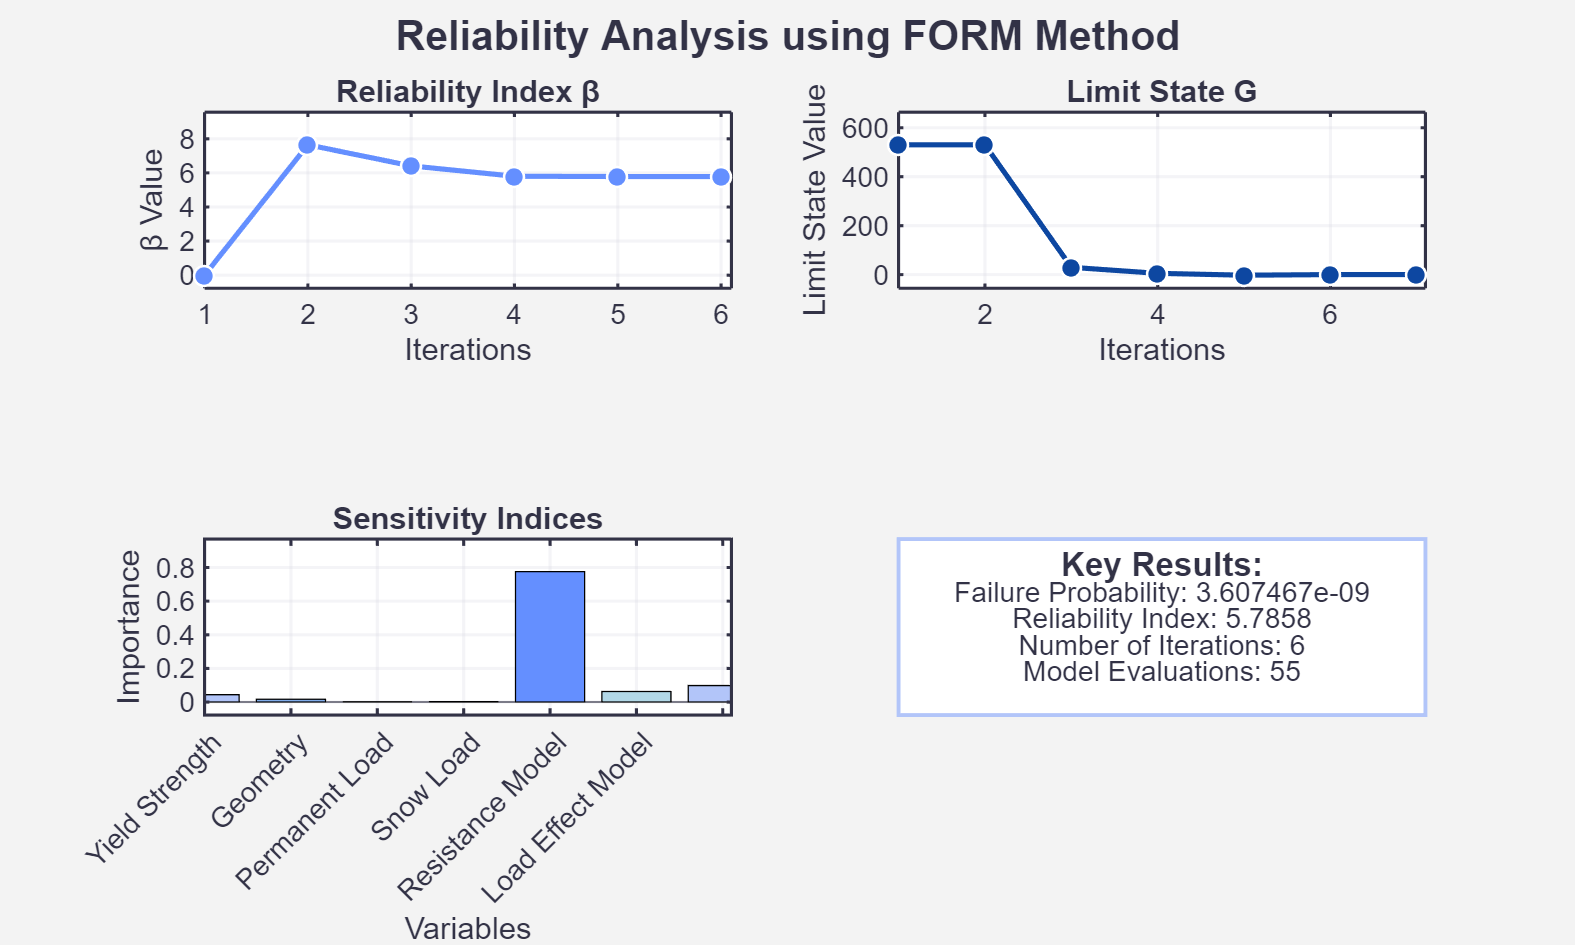

Grafy byly uloženy do: Plots\RA



% Save graph
if ~exist('Plots', 'dir')
   mkdir('Plots')
end

% Použití s exportem (zobrazení a uložení grafů)
plotReliabilityForPoster(reliability,'Plots/RA');

if false
Print key numerical results
fprintf('\nKey Reliability Analysis Results:\n');
fprintf('Failure Probability: %e\n', results.Pf);
fprintf('Reliability Index: %.4f\n', results.BetaHL);
fprintf('Number of Iterations: %d\n', results.Iterations);
fprintf('Number of Model Evaluations: %d\n', results.ModelEvaluations);

% Interpretation of results
fprintf('\nResults Interpretation:\n');
fprintf('- Extremely low failure probability (%.2e)\n', results.Pf);
fprintf('- High reliability index (%.4f)\n', results.BetaHL);
fprintf('- Convergence achieved in %d iterations\n', results.Iterations);
end

## Comparison of Probabilistic and Eurocode Safety Levels

%% Reliability Analysis vs. Cross-Sectional Area Ratio
% This section analyzes how reliability index (beta) and resistance-to-load ratio (R_d/E_d) 
% change based on the ratio of actual cross-sectional area (A_g) to Eurocode required area (A_s_EN)

displayOriginalValues(section,EN);


Original cross-sectional area values:
Original section area (A_s): 0.001616 m² (1615.93 mm²)
Eurocode required area (A_s_EN): 0.001022 m² (1022.01 mm²)
Original ratio (A_s/A_s_EN): 1.5811


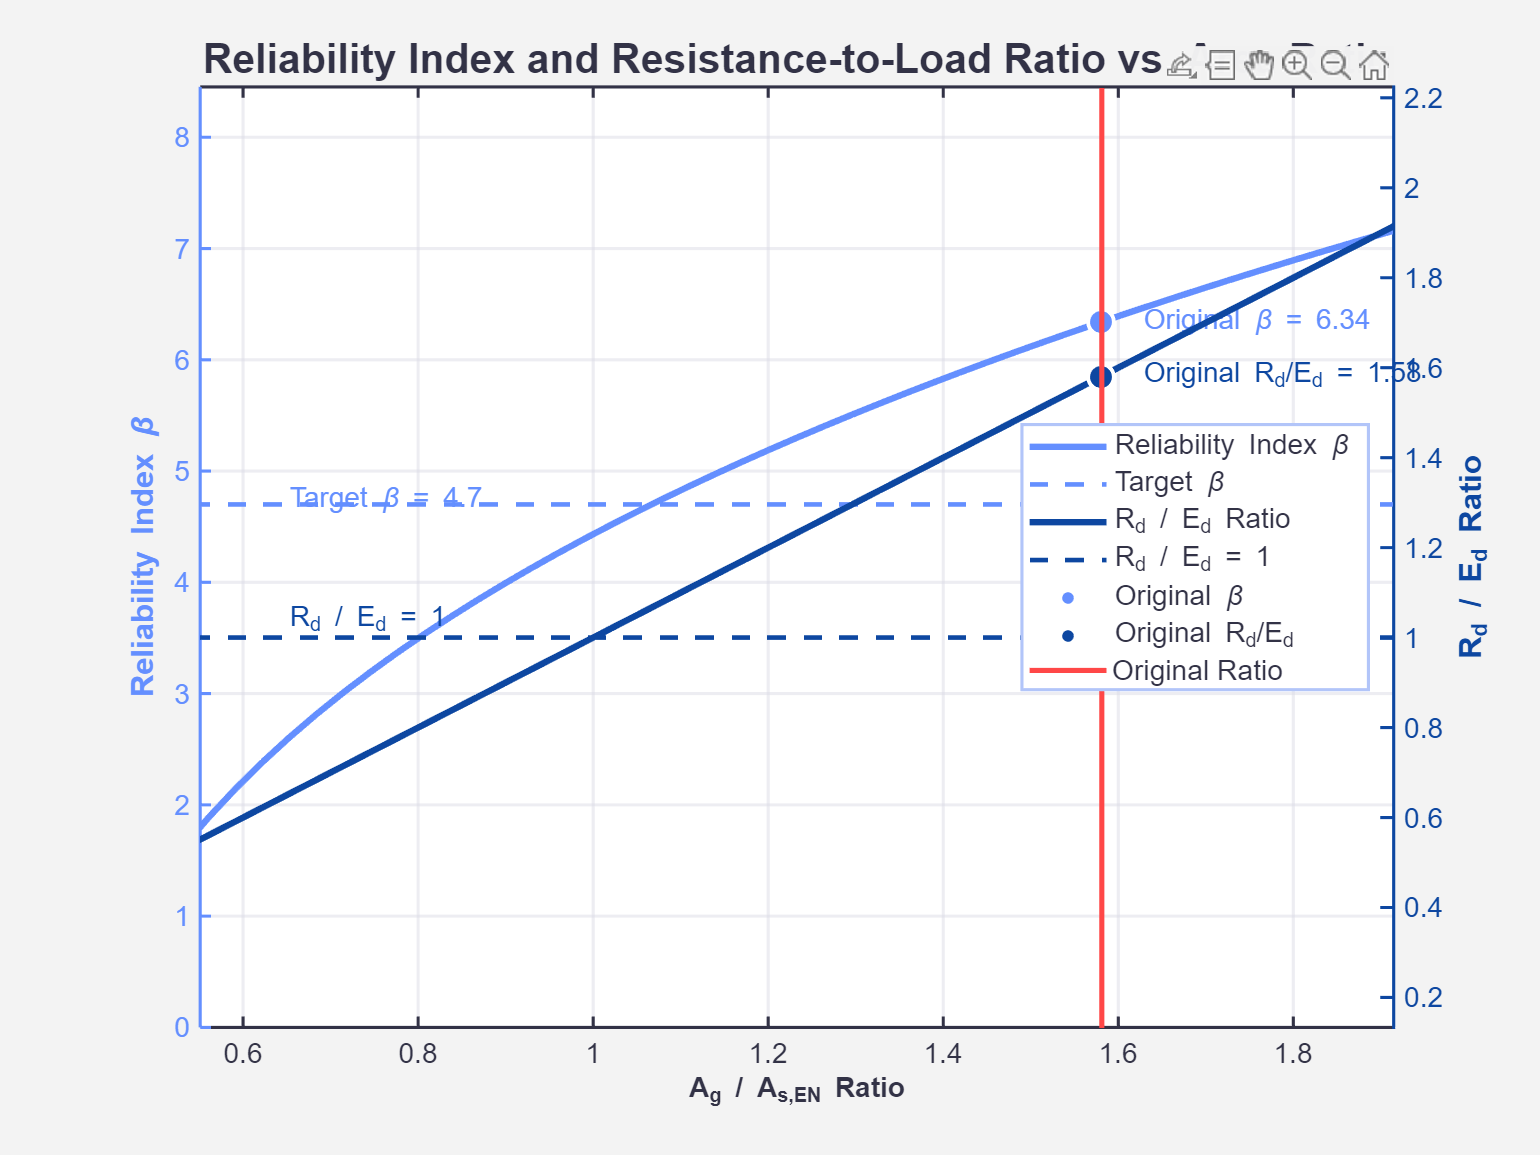

Graf byl uložen do: Plots\reliability_analysis

Safety at original cross-section area:
Reliability index (β) at original area: 6.3414
R_d/E_d ratio at original area: 1.5811

Minimum A_g/A_s,EN ratio needed to achieve target reliability (β = 4.7): 1.082
Minimum A_g/A_s,EN ratio needed for R_d/E_d ≥ 1: 0.990



% Define the range of ratios A_g/A_s_EN to analyze
ratio_range = linspace(0.5, 2.0, 50);  % Ratio from 0.5 to 2.0 times A_s_EN
beta_values = zeros(size(ratio_range));
rd_ed_ratio = zeros(size(ratio_range));

% Store original section area for reference
original_area = section.A_s;
original_EN_area = EN.A_s_en;
original_ratio = original_area / original_EN_area;

% Loop through each ratio value
for i = 1:length(ratio_range)
    % Calculate new section area based on the ratio
    section.A_s = original_EN_area * ratio_range(i);
    
    % Update the geometry variable in the probabilistic model
    model.a.nominal = section.A_s;
    model.a.variable = createUQVariable(model.a, 'A');
    InputOpts.Marginals(2) = model.a.variable;
    
    % Update input object
    inputOpts.Marginals = InputOpts.Marginals;
    input = uq_createInput(inputOpts);
    
    % Run reliability analysis
    reliability = uq_createAnalysis(SimOpts);
    
    % Store the reliability index for this ratio
    beta_values(i) = reliability.Results.BetaHL;
    
    % Calculate and store R_d/E_d ratio
    EN.R_d = section.A_s * section.f_y / EN.gamma_M0;
    rd_ed_ratio(i) = EN.R_d / EN.E_d;
end

% Reset section area to original value after analysis
section.A_s = original_area;

%Plots
plotReliabilityVsAreaRatio(ratio_range, beta_values, rd_ed_ratio, original_ratio, 'Plots/reliability_analysis');